% Modelling ML

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

% ********** 1) Baseline Models **********

% 1a) Baseline Decision Tree
disp('Baseline Decision Tree')
% Train
dt_base = fitctree(X_train, y_train);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

% 1b) Baseline Random Forest
disp('Baseline Random Forest')
% Train
tree = templateTree();
rf_base = fitcensemble(X_train, y_train, 'Method', 'Bag', 'Learners', tree)
% Evaluate
test_model(rf_base, X_test, y_test)

% ********** 2) Tuned Models **********

% Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train)
c = cvpartition(nrow,'KFold', 10)

% 2a) Optimized Tree with CV
rng(1) % for reproducability
% Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
prune = optimizableVariable('prune', {'on','off'},'Type','categorical'); % default: 'on'
PruneCriterion = optimizableVariable('PruneCriterion',  {'error', 'impurity'}, 'Type','categorical'); % default: 'error'
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 20],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 20], 'Type', 'integer');  % default: 1
ParamsDT= [prior, prune, PruneCriterion, MaxNumSplit, MinLeafSize];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_dt_cv(params,X_train,y_train, c), ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

% Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'prior', char(z.prior), 'prune', char(z.prune), ...
    'PruneCriterion', char(z.PruneCriterion), 'MaxNumSplits', z.MaxNumSplit, 'MinLeafSize', z.MinLeafSize);

% Evaluate
test_model(dt_best, X_test, y_test)

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | MaxNumSplits |  MinLeafSize | NumVariables-| SplitCriteri-|        prior | NumLearningC-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | ToSample     | on           |              | ycles        |
|=================================================================================================================================================================|
|    1 | Best   |           1 |       35.66 |           1 |           1 |           63 |           28 |           17 |       twoing |    empirical |          320 |
|    2 | Best   |     0.78355 |      82.492 |     0.78355 |     0.82051 |           71 |           12 |           11 |     deviance |      uniform |          789 |
|    3 | Accept 

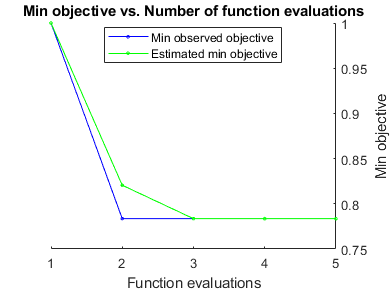


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 5 reached.
Total function evaluations: 5
Total elapsed time: 234.5424 seconds
Total objective function evaluation time: 229.9737

Best observed feasible point:
    MaxNumSplits    MinLeafSize    NumVariablesToSample    SplitCriterion     prior     NumLearningCycles
    ____________    ___________    ____________________    ______________    _______    _________________

         71             12                  11                deviance       uniform           789       

Observed objective function value = 0.78355
Estimated objective function value = 0.78356
Function evaluation time = 82.4925

Best estimated feasible point (according to models):
    MaxNumSplits

% 2b) Optimized Random Forest with CV
rng(1) % for reproducability
% Tree variables
MaxNumSplits = optimizableVariable('MaxNumSplits',[1, 100],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1
NumVariablesToSample = optimizableVariable('NumVariablesToSample', [1, 17], 'Type', 'integer');  % default: 1
SplitCriterion = optimizableVariable('SplitCriterion', {'gdi', 'deviance', 'twoing'},'Type','categorical'); % default: 'empirical'
% Forest variables
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
NumLearningCycles = optimizableVariable('NumLearningCycles', [10, 1000], 'Type', 'integer');  % default: 1
ParamsRF = [MaxNumSplits, MinLeafSize, NumVariablesToSample, SplitCriterion, prior, NumLearningCycles];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_rf_cv(params,X_train,y_train, c), ParamsRF,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 5, 'GPActiveSetSize', 1000, 'Verbose',1);

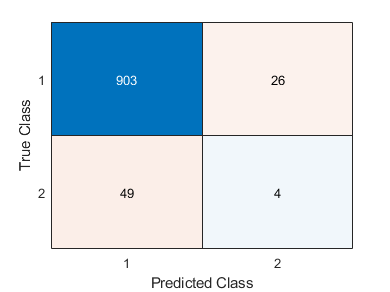

accuracy = 0.9236

precision = 0.1333

recall = 0.0755

specificity = 0.9720

fb = 0.0964


% Train optimized model on entire data set
z = bestPoint(results);
tree = templateTree('MaxNumSplits', z.MaxNumSplits, 'MinLeafSize', z.MinLeafSize, 'SplitCriterion', char(z.SplitCriterion), ...
    'NumVariablesToSample', z.NumVariablesToSample, 'NumLearningCycles', z.NumLearningCycles);
rf_best = fitcensemble(X_train, y_train, 'Method', 'Bag', 'prior', char(z.prior));

% Evaluate
test_model(rf_best, X_test, y_test)

function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    % Evaluation metrics for binary classification
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);
    %confusionchart(cmat);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end

% Test model without CV folds
function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    confusionchart(cmat);
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, ...
             'prior', char(params.prior), 'prune', char(params.prune), ...
             'PruneCriterion', char(params.PruneCriterion), ...
             'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% RF function CV
function fb = fb_loss_rf_cv(params, X_train, y_train, cv_part)
        % Train model (TreeBagger has no CV parameter)
        tree = templateTree('MaxNumSplits', params.MaxNumSplits, 'MinLeafSize',params.MinLeafSize, ...
            'SplitCriterion', char(params.SplitCriterion), 'NumVariablesToSample', params.NumVariablesToSample);
        model = fitcensemble(X_train, y_train, 'Method', 'Bag', 'CVPartition', cv_part, ...
               'Options', statset('UseParallel',true), ...
               'Learners', tree, 'prior', char(params.prior), ...
               'NumLearningCycles', params.NumLearningCycles);
            
        % Calculate F-beta score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end
%#ok<*ASGLU,*NOPRT> 